**c) **Given Data

kg = 8.956; tm = 1.565;
km = 50; ke = 3183;

numg = kg*km*ke/tm;
deng = poly([0 -1/tm]);
G = tf(numg,deng)

G =
 
    9.108e05
  -------------
  s^2 + 0.639 s
 
Continuous-time transfer function.



Tr = 0.025s and %OS = 1; z and wn are evaluated

pos = input("Enter the value of pos")

pos = 1

z = -log(pos/100)/sqrt(pi^2+(log(pos/100))^2)

z = 0.8261

wn = 103

wn = 103

Plot the uncompensated system

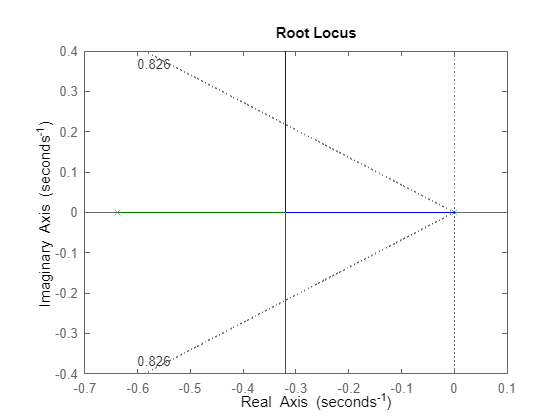

clf
rlocus(G)
sgrid(z,wn)

Specific Gain, K is selected on the uncompensated RL plot

and step response for closed loop system is plotted

[K,p] = rlocfind(G)

Select a point in the graphics window


selected_point = -0.3189 + 0.2184i

K = 1.6443e-07

p =   -0.3195 + 0.2184i
  -0.3195 - 0.2184i


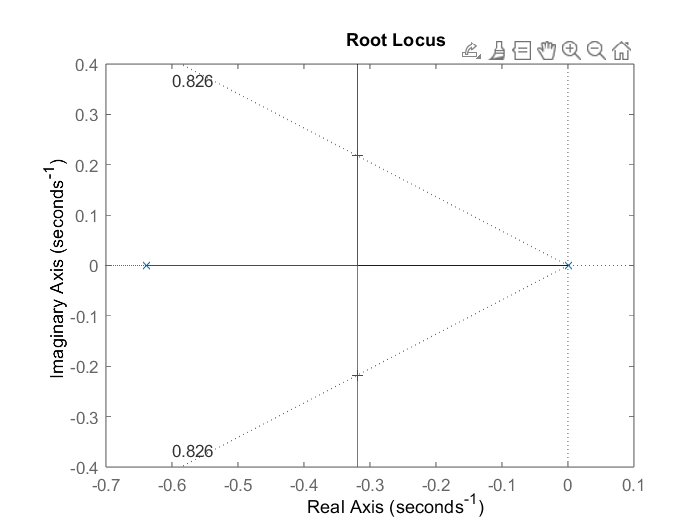

sgrid(z,wn)

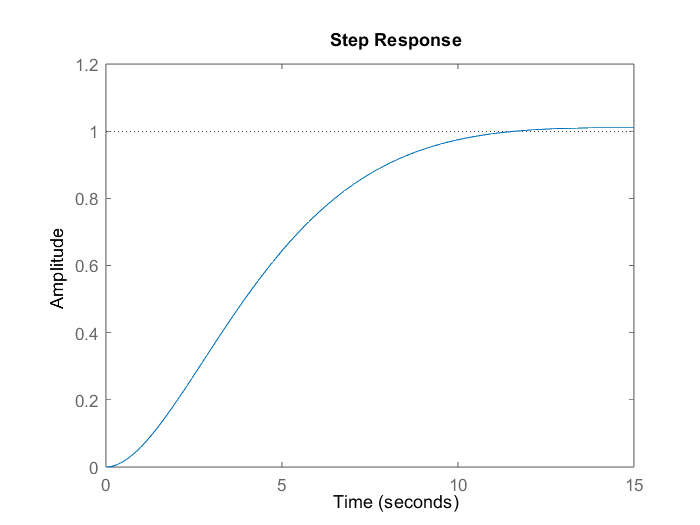

T = feedback(G*K,1);
step(T)

It is observed that %OS =1 is satisfied for uncompensated system

**Design of PD controller**

The desired point is calculated based on z and wn

The angle made by open loop poles is also calculated based on which the position of zero of PD controller is decided

x = -z*wn ;
y = x*tan(acos(z));
desired_pole = x+1i*y

desired_pole = -85.0868 - 58.0452i

angle_at_desired_pole = (180/pi)*angle(polyval(numg,desired_pole)/polyval(deng,desired_pole));
PD_angle = 180+angle_at_desired_pole

PD_angle = 111.1960

zc = -y/tan(PD_angle)+x;

RL plot of the compensated system is made

Gc = tf([1 -zc],1)

Gc =
 
  s + 65.17
 
Continuous-time transfer function.



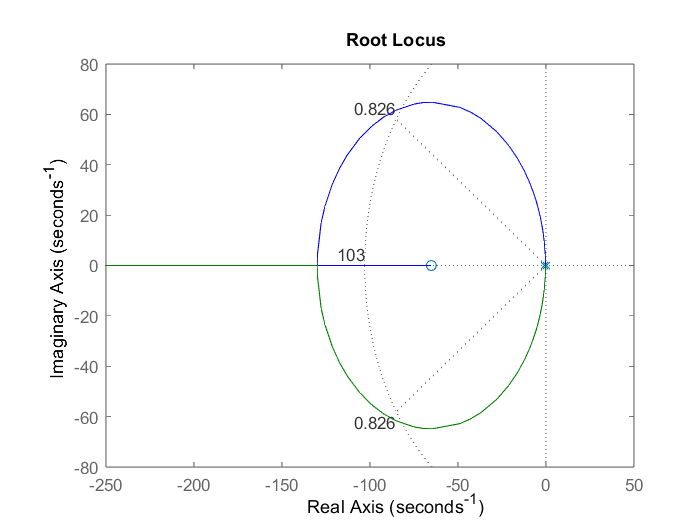

Ge = G*Gc;
rlocus(Ge)
sgrid(z,wn)

Select appropriate gain value on RL to be close to the design point

Select a point in the graphics window


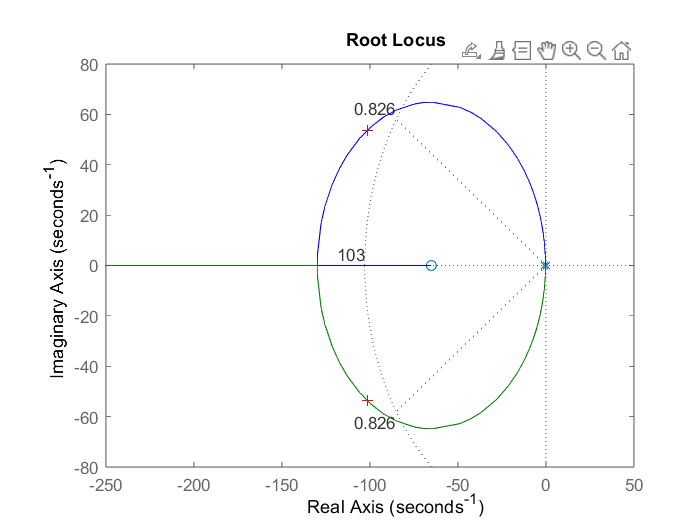

selected_point = -1.0142e+02 + 5.3598e+01i

[K,p] = rlocfind(Ge);

p

p = 1.0e+02 *

  -1.0150 + 0.5371i
  -1.0150 - 0.5371i


K

K = 2.2219e-04

For closed loop, we have p1,p2 = -86.9+_61i and z1 = -65.2

Therefore dominant pole approximation does not hold true

Plot the step response for the compensated system and we find that requirements are not met

as dominant pole approximation doesnot hold true.

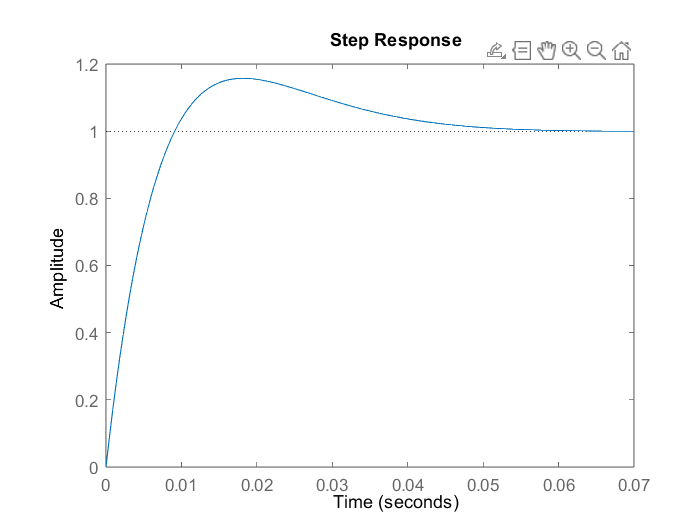

T = feedback(K*Ge,1);
step(T)

**Conclusion:**

- For the given system, with the requirements, the design point is fixed.

- By angle criterion there exists unique 'zero' that can be positioned to satisfy the requirements

- By compensating with that zero, we find that 2nd order approximaton does not hold true and hence the requirements are not met

**Inspection:**

It can be said that the zero cannot be put to the left of the poles  for the requirement to be met. It has to be put in between the poles to get a second order dominant pole approximation,

As a simple case, zero can be put at the pole -1/tm which reduces the system into a first order system => no OS

Appropriate gain can be selected to meet the time requirement

zc = 1/tm;

Reduce to first order system by compensation

Gc = tf([1 zc],1)

Gc =
 
  s + 0.639
 
Continuous-time transfer function.



Ge = G*Gc;
Ge = minreal(Ge)

Ge =
 
  9.108e05
  --------
     s
 
Continuous-time transfer function.



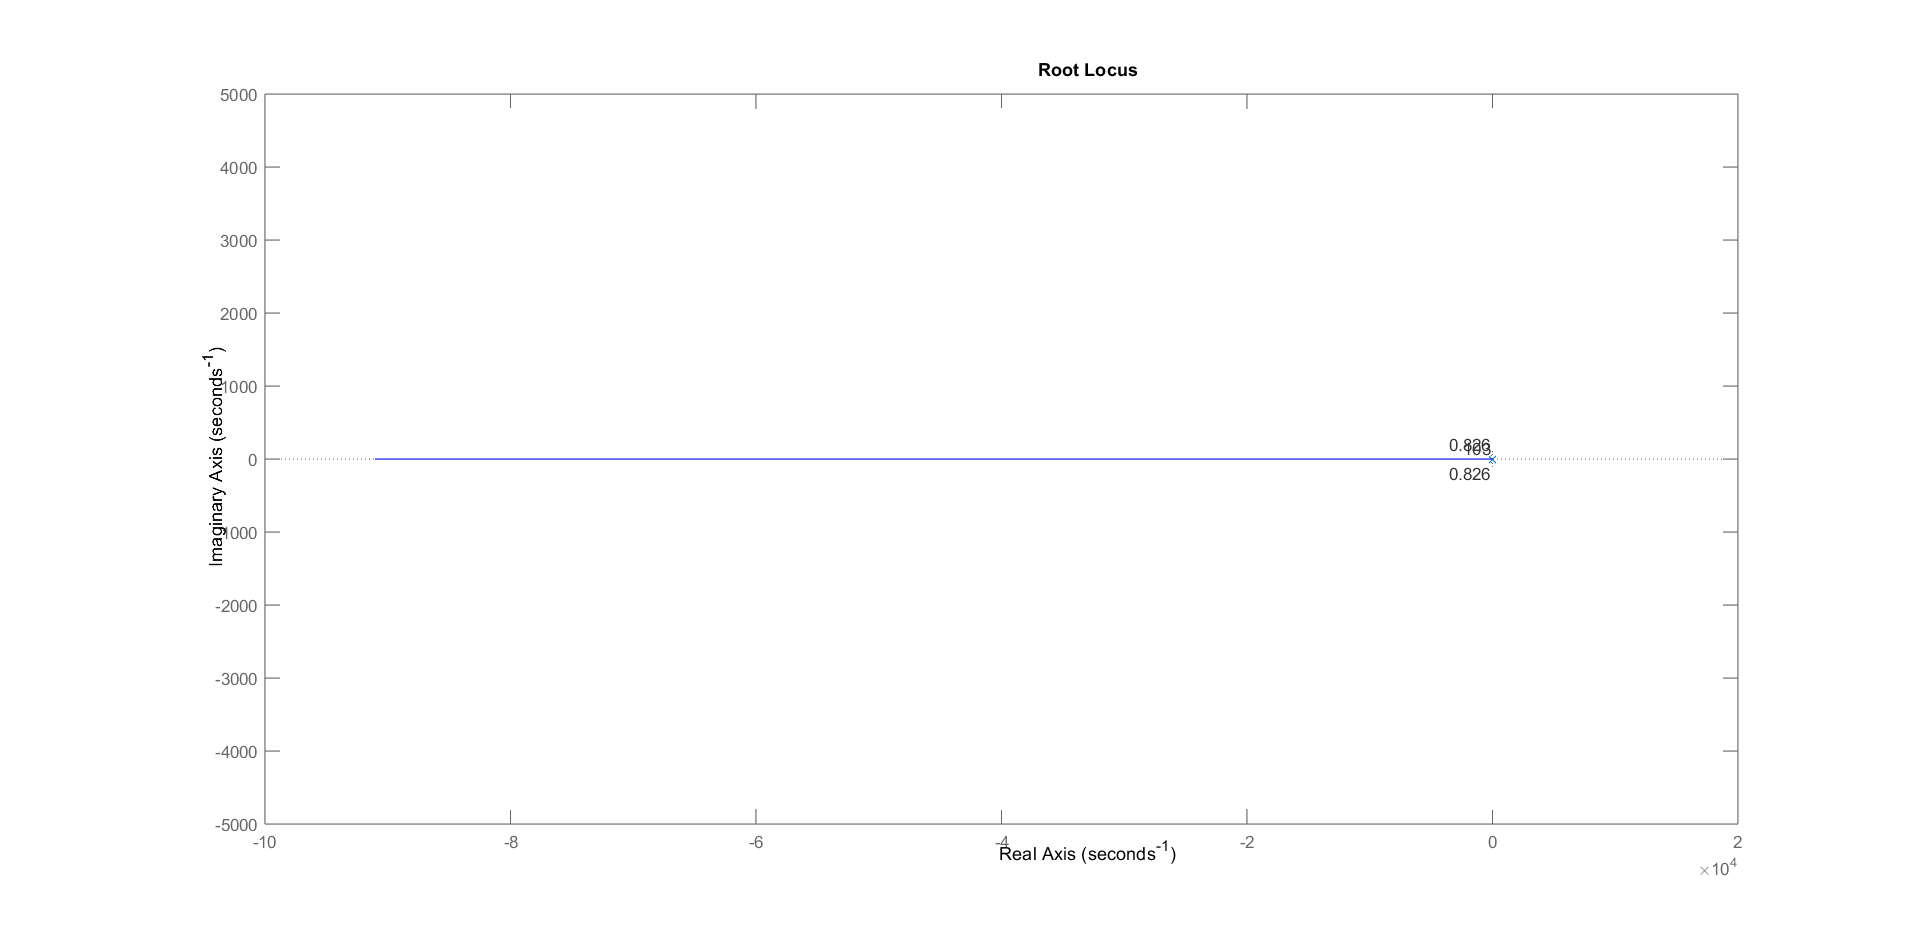

rlocus(Ge,0:0.0001:0.1)
sgrid(z,wn)

Select appropriate gain

[K,p] = rlocfind(Ge);

Select a point in the graphics window


p
K

Obtain the step response

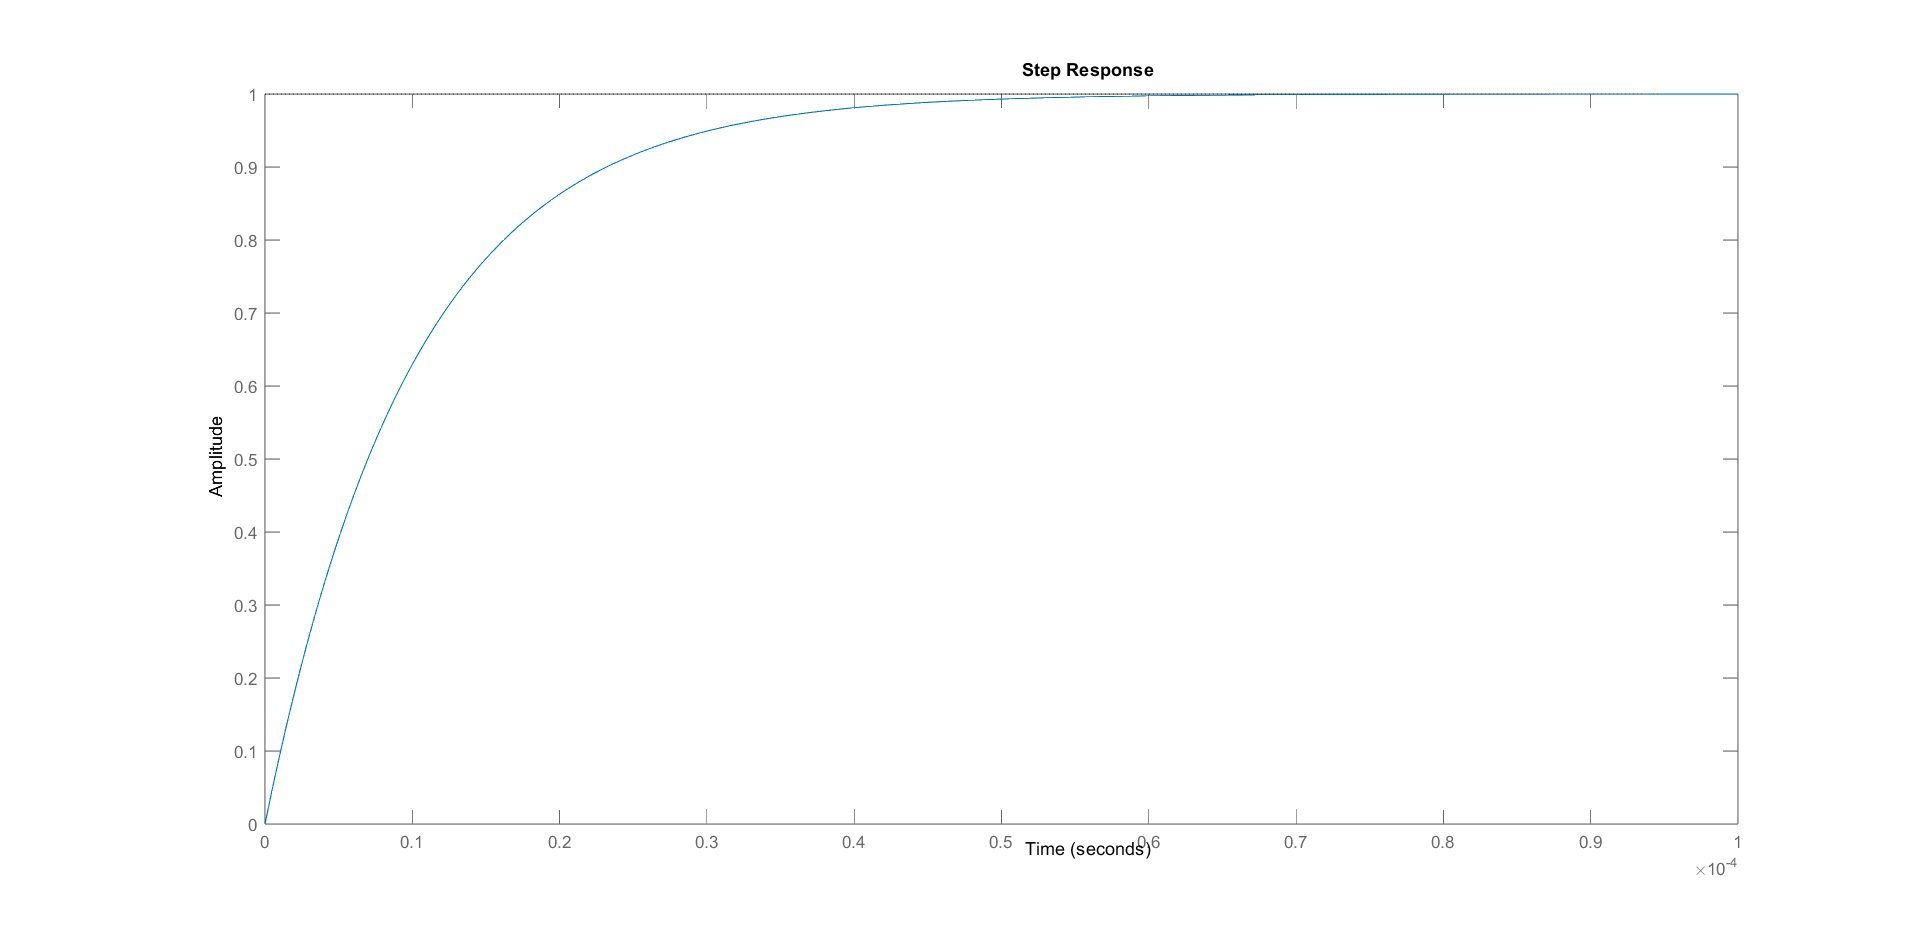

T = feedback(K*Ge,1);
step(T)

**Requirements : %OS = 1; Tr = 25ms**

**We find %OS = 0; Tr = 0.03ms**

**Hence the requirements are met by placing zero at 0.639 at a gain of 1.0975**

**Kp and Kd values are as below**

**Note: Gain should be choosen based on practical realisaiton**

Kp = K*zc

Kp = 0.0697

Kd = K

Kd = 0.1090

**e) To plot the frequency response graph (magnitude) of closed-loop disturbance transfer function Gd(s)**

G2 = tf(km*ke,[1 0])

G2 =
 
  159150
  ------
    s
 
Continuous-time transfer function.



H2 = tf(kg/tm,[1 1/tm])

H2 =
 
    5.723
  ---------
  s + 0.639
 
Continuous-time transfer function.



Gd = feedback(G2,H2)

Gd =
 
    159150 s + 1.017e05
  ------------------------
  s^2 + 0.639 s + 9.108e05
 
Continuous-time transfer function.



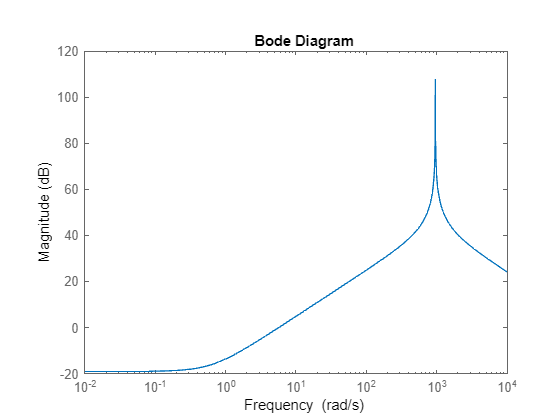

bodemag(Gd)

**f) **ess = 10.15 counts for step input of 10^s counts with a constant negative disturbance torque of 10 Nm